# **Week L7: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser ac cording to an electrical signal

### Alamouti Coding

clearvars

% Parameters
NSymb = 200000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% Generating random bit sequence(s)
sourceBitsQAM = randi([0 1], NSymb*4, 1); % Matrix of source bits for QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true); % Maps source bit vector to symbol vector
codedSymbolsQAM = AlamoutiCoding(sourceSymbolsQAM); % Encodes symbols using Alamouti coding

vI_QAM = real(codedSymbolsQAM);
vQ_QAM = imag(codedSymbolsQAM);

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QAM")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

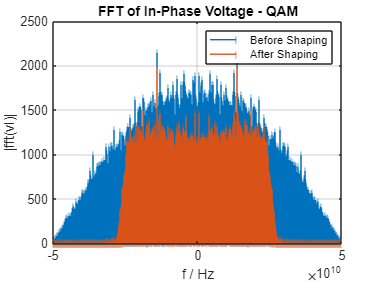

% RRC filter parameters
filterSpan = 20; % Span of RRC filter in no. of symbols
rollOff = 0.1;
filterResponse = rcosdesign(rollOff, filterSpan, SpS, "sqrt")';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

% stem(filterResponse_t, filterResponse, '-o');
% title('Impulse Response of RRC Filter - upfirdn');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% stem(filterResponse_t, RRC(filterSpan, SpS, rollOff), '-o');
% title('Impulse Response of RRC Filter - PulseShaping');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% rcosdesignPw = mean(abs(filterResponse).^2)
% RRCPw = mean(abs(RRC(filterSpan, SpS, rollOff)).^2)

% ---------------------------------------------------------------------------

% Using RRC filter to shape vI and vQ
vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1);

% vI_QAM_shaped = PulseShaping(vI_QAM, SpS, filterSpan, rollOff); 
% vQ_QAM_shaped = PulseShaping(vQ_QAM, SpS, filterSpan, rollOff); 

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QAM), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
title("FFT of In-Phase Voltage - QAM");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on


% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QAM");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 5.5000e+10

### IQ Modulation

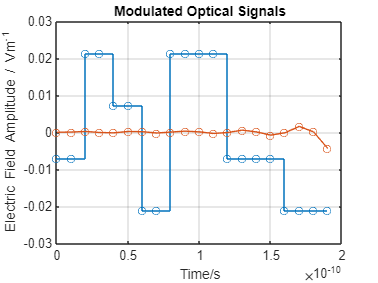

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a continuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 2); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 2); % Laser output to be used with shaped signals

% Visualising output from laser
% plot(t(1:20), real(laserE(1:20)), "o-");
% title("Laser Output as a Continous Wave");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}");
% grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQAM = (vI_QAM_upsampled+1i*vQ_QAM_upsampled).*laserE;
modOpticSigQAM_shaped = (vI_QAM_shaped+1i*vQ_QAM_shaped).*laserE_shaped;

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
hold on
plot(t(1:10*SpS), real(modOpticSigQAM_shaped(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
grid on
hold off

### Controlling Effects

% Setting the required effects:

insertCD = false;

singleRotation = true;
multipleRotations = false;

if (singleRotation && multipleRotations == true)
    error('You can only apply either a single rotation or multiple rotations at a given time')
end

insertAWGN = true;

if insertAWGN && multipleRotations
    error('Insertion of AWGN with multiple polarization rotation angles cannot be performed together')
end

CDcompensate = false;

if CDcompensate && ~insertCD
    error('Cannot compensate for CD if it is not added in the first place')
end


## Optical Channel

### Inserting CD

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

clear channelOutQAM channelOutQAM_shaped

if insertCD
    channelOutQAM = CDInsertion(modOpticSigQAM, SpS, Rs, D, CLambda, linkLength, 2); 
    channelOutQAM_shaped = CDInsertion(modOpticSigQAM_shaped, SpS, Rs, D, CLambda, linkLength, 2); 
else
    channelOutQAM = modOpticSigQAM;
    channelOutQAM_shaped= modOpticSigQAM_shaped;
end

% Debugging addition of CD through immediate CD compensation

% channelOutQAM_shaped_filtered = upfirdn(channelOutQAM_shaped(:,1), filterResponse, 1, SpS);
% channelOutQAM_shaped_filtered = channelOutQAM_shaped_filtered(filterSpan+1:end-filterSpan);
% 
% debugCDC = OverlapSaveCDC(channelOutQAM(:,1),D,linkLength,CLambda,Rs,1,SpS,2^8,50);
% debugCDC_shaped = OverlapSaveCDC(channelOutQAM_shaped,D,linkLength,CLambda,Rs,1,SpS,2^8,50);
% 
% % Evaluating BER when CDC is applied after filtering
% % debugCDC_shaped_filtered = debugCDC_shaped;
% % debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% % 
% % debugCDC_shaped_filtered_Ints = qamdemod(debugCDC_shaped_filtered, 16, UnitAveragePower=true);
% % debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 4);
% % [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQAM)
% 
% % Evaluating BER when CDC is applied before filtering
% debugCDC_shaped_filtered = upfirdn(debugCDC_shaped, filterResponse, 1, SpS);
% debugCDC_shaped_filtered = debugCDC_shaped_filtered(filterSpan+1:end-filterSpan);
% debugCDC_shaped_filtered(2:2:end) = -conj(debugCDC_shaped_filtered(2:2:end));
% 
% debugCDC_shaped_filtered_Ints = qamdemod(debugCDC_shaped_filtered, 16, UnitAveragePower=true);
% debugCDC_shaped_filtered_Bits = int2bit(debugCDC_shaped_filtered_Ints, 4);
% [~, BER_debugCDC_shaped] = biterr(debugCDC_shaped_filtered_Bits, sourceBitsQAM)
% 
% % Visualising symbol distributions
% plot(channelOutQAM(:,1), ".");
% hold on
% plot(debugCDC, ".");
% plot(modOpticSigQAM(:,1), '+', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off
% 
% plot(channelOutQAM_shaped(:,1), ".");
% hold on
% plot(debugCDC_shaped, ".");
% plot(modOpticSigQAM_shaped(:,1), '.', Linewidth=2);
% title("Distorted Symbol Distribution with CD - Unshaped");
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before CD comp.", "After CD comp.", "Original")
% grid on
% hold off

### Inserting Polarization Rotations and/or Phase Shifts

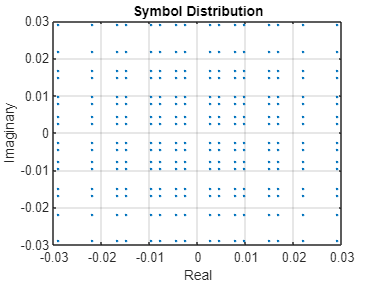

% Inserting rotations and/or phase shifts

if singleRotation
    theta = 60; phi = 0;
    channelOutQAM = PolRotate(channelOutQAM, theta, phi); % Unshaped
    channelOutQAM_shaped = PolRotate(channelOutQAM_shaped, theta, phi); % Shaped

    plot(channelOutQAM(:,1), '.')
    title("Symbol Distribution")
    xlabel("Real")
    ylabel("Imaginary")
    grid on

elseif multipleRotations
    thetaArr=[45 60 80 90]; phi=0;
    channelOutQAM = repelem(channelOutQAM,1,1,length(thetaArr)); % Unshaped
    channelOutQAM_shaped = repelem(channelOutQAM_shaped,1,1,length(thetaArr)); % Shaped

    for i=1:length(thetaArr)
        channelOutQAM(:,:,i) = PolRotate(channelOutQAM(:,:,i), thetaArr(i), phi); % Unshaped
        channelOutQAM_shaped(:,:,i) = PolRotate(channelOutQAM_shaped(:,:,i), thetaArr(i), phi); % Shaped
    end

    plot(channelOutQAM_shaped(:,1)/sqrt(laserPw_Lin/2), '.')
    hold on
    plot(channelOutQAM(:,1)/sqrt(laserPw_Lin/2), '.')
    title("Symbol Distribution")
    xlabel("Real")
    ylabel("Imaginary")
    legend("Shaped", "Unshaped")
    grid on
    hold off
end

### Adding AWGN

% Adding AWGN to the modulated optical signal

if insertAWGN
    SNRb_dB = [0:2.5:10]; % SNR per bit in dB
    SNRb_Lin = 10.^(SNRb_dB/10); % linear SNR per symbol

    channelOutQAM = repelem(channelOutQAM, 1, 1, length(SNRb_dB));
    channelOutQAM_shaped = repelem(channelOutQAM_shaped, 1, 1, length(SNRb_dB));
    noisePw = zeros(1,length(SNRb_dB)); 
    noisePw_shaped = zeros(1,length(SNRb_dB));

    for i=1:length(SNRb_dB)
        [channelOutQAM(:,:,i), noisePw(1,i)] = awgn(channelOutQAM(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=4), 'measured'); % Unshaped
        [channelOutQAM_shaped(:,:,i), noisePw_shaped(1,i)] = awgn(channelOutQAM_shaped(:,:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=2, bitspersymbol=4), 'measured'); % Shaped
    end
end

% Debugging AWGN addition

% sigPw = mean(abs(modOpticSigQAM(:,1)).^2 + abs(modOpticSigQAM(:,2)).^2)
% sigPw_shaped = mean(abs(modOpticSigQAM_shaped(:,1)).^2 + abs(modOpticSigQAM_shaped(:,2)).^2)
% 
% noisePw
% noisePw_shaped
% debugSNR = 10*log10(0.5*sigPw./noisePw) - 10*log10(2)
% debugSNR_shaped = 10*log10(0.5*sigPw_shaped./noisePw_shaped) - 10*log10(2)
% 
% %--------------------------------------------------------------------------------
% 
% % Visualising in-phase voltage with and without noise
% stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), '-o');
% hold on
% stairs(t(1:10*SpS), real(channelOutQAM(1:10*SpS,1)), '-o');
% title("In-Phase Electric Field");
% xlabel("Time / s");
% ylabel("Electric Field / Vm^{-1}");
% legend("Without AWGN", "With AWGN");
% grid on
% hold off
% 
% % Visualising Symbol Distribution
% plot(channelOutQAM(:,1,1), '.');
% hold on
% plot(channelOutQAM(:,1,end), '.');
% plot(sourceSymbolsQAM(:,1)*sqrt(laserPw_Lin/2), '+', Linewidth=2);
% title("Symbol Distribution with AWGN");
% xlabel("real");
% ylabel("Imaginary")
% grid on
% hold off
% 
% BERQAM_AWGN_test = zeros(1,length(SNRb_dB)); 
% BERQAM_shaped_filtered_AWGN_test = zeros(1,length(SNRb_dB)); BERQAM_shaped_unfiltered_AWGN_test = zeros(1,length(SNRb_dB));
% 
% % Unshaped
% channelOutQAM_test = channelOutQAM(1:SpS:end,1,:); channelOutQAM_test(2:2:end,1,:) = -1*conj(channelOutQAM_test(2:2:end,1,:));
% 
% % Shaped
% channelOutQAM_reshaped = reshape(channelOutQAM_shaped(:,1,:),samples,size(channelOutQAM_shaped,3),1);
% 
% % After matched filtering
% channelOutQAM_shaped_filtered_test = upfirdn(channelOutQAM_reshaped, filterResponse, 1, SpS); 
% channelOutQAM_shaped_filtered_test = channelOutQAM_shaped_filtered_test(filterSpan+1:end-filterSpan,:,:);
% channelOutQAM_shaped_filtered_test(2:2:end,:) = -1*conj(channelOutQAM_shaped_filtered_test(2:2:end,:));
% 
% % Before matched filtering
% channelOutQAM_shaped_unfiltered_test = channelOutQAM_reshaped(1:SpS:end,:);
% channelOutQAM_shaped_unfiltered_test = channelOutQAM_shaped_unfiltered_test(filterSpan/2+1:end-filterSpan/2,:);
% channelOutQAM_shaped_unfiltered_test(2:2:end,:) = -1*conj(channelOutQAM_shaped_unfiltered_test(2:2:end,:));
% 
% for i=1:length(SNRb_dB)
%     % Unshaped
%     IntsQAM_AWGN_test = qamdemod(channelOutQAM_test(:,1,i), 16, UnitAveragePower=true);
%     BitsQAM_AWGN_test = int2bit(IntsQAM_AWGN_test, 4);
%     [~, BERQAM_AWGN_test(1,i)] = biterr(BitsQAM_AWGN_test, sourceBitsQAM);
% 
%     % Shaped - Unfiltered
%     IntsQAM_shaped_unfiltered_AWGN_test = qamdemod(channelOutQAM_shaped_unfiltered_test(:,i,1), 16, UnitAveragePower=true);
%     BitsQAM_shaped_unfiltered_AWGN_test = int2bit(IntsQAM_shaped_unfiltered_AWGN_test, 4);
%     [~, BERQAM_shaped_unfiltered_AWGN_test(1,i)] = biterr(BitsQAM_shaped_unfiltered_AWGN_test, sourceBitsQAM);
% 
%     % Shaped - Filtered
%     IntsQAM_shaped_filtered_AWGN_test = qamdemod(channelOutQAM_shaped_filtered_test(:,i,1), 16, UnitAveragePower=true);
%     BitsQAM_shaped_filtered_AWGN_test = int2bit(IntsQAM_shaped_filtered_AWGN_test, 4);
%     [~, BERQAM_shaped_filtered_AWGN_test(1,i)] = biterr(BitsQAM_shaped_filtered_AWGN_test, sourceBitsQAM);
% end
% 
% semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
% hold on
% semilogy(SNRb_dB, BERQAM_AWGN_test', 'k+');
% semilogy(SNRb_dB, BERQAM_shaped_unfiltered_AWGN_test', 'o');
% semilogy(SNRb_dB, BERQAM_shaped_filtered_AWGN_test', '-*');
% title("BER vs. SNR for QAM");
% ylabel("BER");
% xlabel("SNR per bit / dB");
% legend("Theoretical", "Unshaped", "Shaped-Unfiltered", "Shaped-Filtered");
% grid on
% hold off

### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 2); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 2); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on

% ---------------------------------------------------------------------------------------

% Generating output from optical front-end
eta_ph = 1; % Responsivity of photodetectors

% Setting size of third dimension
if multipleRotations
    OpticFEOut_3d = length(thetaArr);
elseif insertAWGN
    OpticFEOut_3d = length(SNRb_dB);
else
    OpticFEOut_3d = 1;
end

OpticFEOutQAM = zeros(size(channelOutQAM,1), 4, OpticFEOut_3d);
OpticFEOutQAM_shaped = zeros(size(channelOutQAM_shaped,1), 4, OpticFEOut_3d);

if multipleRotations || insertAWGN
    for i=1:OpticFEOut_3d
        OpticFEOutQAM(:,:,i) = OpticalFrontEnd(channelOutQAM(:,:,i), Elo, eta_ph, 2); % Unshaped
        OpticFEOutQAM_shaped(:,:,i) = OpticalFrontEnd(channelOutQAM_shaped(:,:,i), Elo_shaped, eta_ph, 2); % Unshaped
    end
else
    OpticFEOutQAM = OpticalFrontEnd(channelOutQAM, Elo, eta_ph, 2); % Unshaped
    OpticFEOutQAM_shaped = OpticalFrontEnd(channelOutQAM_shaped, Elo_shaped, eta_ph, 2); % Unshaped
end

% ---------------------------------------------------------------------------------------

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QAM
OpticFEOutQAM_I = TIA_Gain*OpticFEOutQAM(:,1:2:end,:); OpticFEOutQAM_Q = TIA_Gain*OpticFEOutQAM(:,2:2:end,:); % Unshaped 
OpticFEOutQAM_shaped_I = TIA_Gain*OpticFEOutQAM_shaped(:,1:2:end,:); OpticFEOutQAM_shaped_Q = TIA_Gain*OpticFEOutQAM_shaped(:,2:2:end,:); % Shaped 

% Debuggin optical front-end
% plot(t(1:10*SpS), real(channelOutQAM_shaped_AWGN_CD(1:10*SpS,1,1)), "-o")
% hold on
% plot(t(1:10*SpS), 100*OpticFEOutQAM_shaped_AWGN_CD_I(1:10*SpS,1,1), "-o")
% title("Comparison of Channel Output with Optic-Front End")
% xlabel("Time / s")
% ylabel("Value")
% legend("Channel Output", "Optic Front-End Output")
% hold off
% grid on

## DSP

### Scaling 

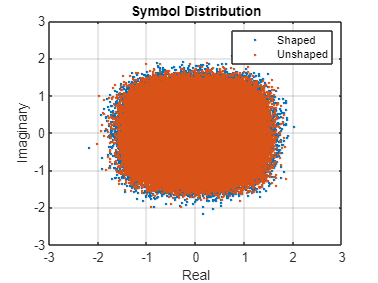

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin/2);
scaleFactor = sqrt(2)*TIA_Gain*eta_ph*laserEMag*laserEMag;
% scaleFactor=1;


% Cancelling the scaling factor:
voltageQAM_I = OpticFEOutQAM_I/scaleFactor; voltageQAM_Q = OpticFEOutQAM_Q/scaleFactor; % Unshaped 

% Shaped
if CDcompensate 
    voltageQAM_shaped_I = OpticFEOutQAM_shaped_I/scaleFactor;
    voltageQAM_shaped_Q = OpticFEOutQAM_shaped_Q/scaleFactor;

elseif ~CDcompensate && (insertAWGN || multipleRotations)
    for i=1:OpticFEOut_3d
        voltageQAM_shaped_I(:,:,i) = upfirdn(OpticFEOutQAM_shaped_I(:,:,i)/scaleFactor, filterResponse, 1, 1);
        voltageQAM_shaped_Q(:,:,i) = upfirdn(OpticFEOutQAM_shaped_Q(:,:,i)/scaleFactor, filterResponse, 1, 1);
    end
    voltageQAM_shaped_filtered = voltageQAM_shaped_I(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:)+1i*voltageQAM_shaped_Q(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);

    plot(voltageQAM_shaped_filtered(:,1,1), ".");
    hold on
    plot(voltageQAM_I(:,1,1)+1i*voltageQAM_Q(:,1,1), ".");
    title("Symbol Distribution");
    xlabel("Real")
    ylabel("Imaginary")
    legend("Shaped", "Unshaped")
    grid on
    hold off

elseif ~CDcompensate
    voltageQAM_shaped_I = upfirdn(OpticFEOutQAM_shaped_I/scaleFactor, filterResponse, 1, 1); voltageQAM_shaped_I = voltageQAM_shaped_I(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);
    voltageQAM_shaped_Q = upfirdn(OpticFEOutQAM_shaped_Q/scaleFactor, filterResponse, 1, 1); voltageQAM_shaped_Q = voltageQAM_shaped_Q(filterSpan*SpS+1:end-filterSpan*SpS+1,:,:);

    voltageQAM_shaped_filtered = voltageQAM_shaped_I+1i*voltageQAM_shaped_Q;
end

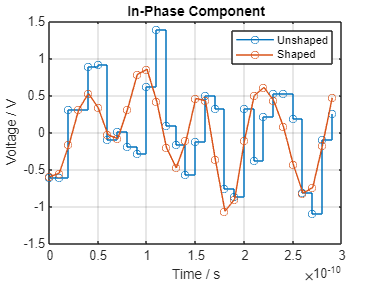


stairs(t(1:30), voltageQAM_I(1:30,1), "-o");
hold on
plot(t(1:30), real(voltageQAM_shaped_filtered(1:30,1)), "-o");
title("In-Phase Component");
xlabel("Time / s")
ylabel("Voltage / V")
legend("Unshaped", "Shaped")
grid on
hold off

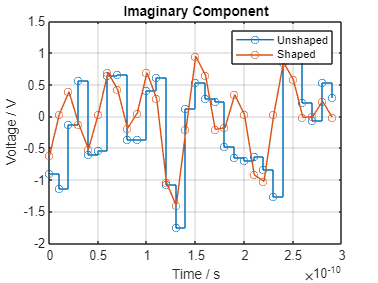


stairs(t(1:30), voltageQAM_Q(1:30,1), "-o");
hold on
plot(t(1:30), imag(voltageQAM_shaped_filtered(1:30,1)), "-o");
title("Imaginary Component");
xlabel("Time / s")
ylabel("Voltage / V")
legend("Unshaped", "Shaped")
grid on
hold off

### Overlap and Save (CDC)

% Applying the overlap and save method for CD compensation

% CD Compensation
c = 299792458; % Speed of light in m/s
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length#

N_CD = 37

N_CD = 50

N_CD = 50

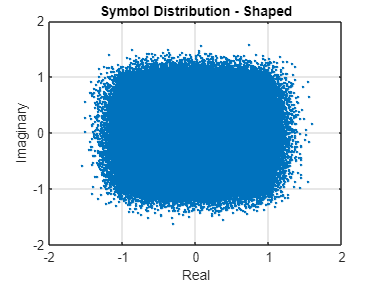

N_FFT = 2^9;

if CDcompensate && (insertAWGN || multipleRotations)
    % Initialising CD compensated vectors
    voltage_CDC = zeros(size(voltageQAM_I,1),OpticFEOut_3d);
    voltage_shaped_CDC = zeros(size(voltageQAM_shaped_I,1),OpticFEOut_3d);
    for i=1:OpticFEOut_3d
        voltageQAM_CDC(:,i) = OverlapSaveCDC(voltageQAM_I(:,1,i)+1i*voltageQAM_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
        voltageQAM_shaped_CDC(:,i) = OverlapSaveCDC(voltageQAM_shaped_I(:,1,i)+1i*voltageQAM_shaped_Q(:,1,i), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);
    end

    % Filtering shaped signals after CD compensation
    for i=1:OpticFEOut_3d
        voltageQAM_shaped_filtered(:,i) = upfirdn(real(voltageQAM_shaped_CDC(:,i)), filterResponse, 1, 1)+1i*upfirdn(imag(voltageQAM_shaped_CDC(:,i)), filterResponse, 1, 1);
    end

    % Removing tails
    voltageQAM_shaped_filtered = voltageQAM_shaped_filtered(filterSpan*SpS+1:end-filterSpan*SpS+1,:);

elseif CDcompensate 
    voltageQAM_CDC = OverlapSaveCDC(voltageQAM_I(:,1)+1i*voltageQAM_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD); % Unshaped

    voltageQAM_shaped_CDC = OverlapSaveCDC(voltageQAM_shaped_I(:,1)+1i*voltageQAM_shaped_Q(:,1), D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD); % Shaped
    voltageQAM_shaped_filtered = upfirdn(real(voltageQAM_shaped_CDC), filterResponse, 1, 1)+1i*upfirdn(imag(voltageQAM_shaped_CDC), filterResponse, 1, 1);
    voltageQAM_shaped_filtered = voltageQAM_shaped_filtered(filterSpan*SpS+1:end-filterSpan*SpS+1);
end

if CDcompensate
    plot(voltageQAM_I(:,1,1)+1i*voltageQAM_Q(:,1,1), '.');
    hold on
    plot(voltageQAM_CDC(:,1), '.');
    title("Symbol Distribution - Unshaped")
    xlabel("Real")
    ylabel("Imaginary")
    legend("Before", "After")
    grid on
    hold off

    plot(voltageQAM_shaped_I(:,1,1)+1i*voltageQAM_shaped_Q(:,1,1), '.');
    hold on
    plot(voltageQAM_shaped_filtered(:,1), '.');
    title("Symbol Distribution - Shaped")
    xlabel("Real")
    ylabel("Imaginary")
    legend("Before", "After")
    grid on
    hold off
else
    plot(voltageQAM_I(:,1,end)+1i*voltageQAM_Q(:,1,end), '.');
    title("Symbol Distribution - Unshaped")
    xlabel("Real")
    ylabel("Imaginary")
    grid on

    plot(voltageQAM_shaped_I(:,1,end)+1i*voltageQAM_shaped_Q(:,1,end), '.');
    title("Symbol Distribution - Shaped")
    xlabel("Real")
    ylabel("Imaginary")
    grid on
end

% New Debugging CD compensation

% Unshaped
% voltageQAM_CDC_debug = voltageQAM_CDC(1:SpS:end,:); voltageQAM_CDC_debug(2:2:end,:) = -conj(voltageQAM_CDC_debug(2:2:end,:));
% IntsQAM_CDC = qamdemod(voltageQAM_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_CDC = int2bit(IntsQAM_CDC, 4);
% [~, BERQAM_CDC] = biterr(BitsQAM_CDC, sourceBitsQAM)
% 
% % Shaped
% voltageQAM_shaped_CDC_debug = voltageQAM_shaped_filtered(1:SpS:end,:);
% voltageQAM_shaped_CDC_debug(2:2:end,:) = -conj(voltageQAM_shaped_CDC_debug(2:2:end,:));
% IntsQAM_shaped_CDC = qamdemod(voltageQAM_shaped_CDC_debug, 16, UnitAveragePower=true);
% BitsQAM_shaped_CDC = int2bit(IntsQAM_shaped_CDC, 4);
% [~, BERQAM_shaped_CDC] = biterr(BitsQAM_shaped_CDC, sourceBitsQAM)
% 
% if insertAWGN
%     semilogy(SNRb_dB, 0.5*erfc(sqrt(10.^(SNRb_dB/10))));
%     hold on
%     semilogy(SNRb_dB, BERQAM_CDC', 'o');
%     semilogy(SNRb_dB, BERQAM_shaped_CDC', '+');
%     title("BER vs. SNR");
%     ylabel("BER");
%     xlabel("SNR per bit / dB");
%     legend("Theoretical", "Unshaped", "Shaped");
%     grid on
%     hold off
% end

### Adaptive Equalziation

% Without channel distortion
NTaps = 5; NRemove = 150000; N1 = 100000; Mu_T = 1e-4; Mu_DD = Mu_T; Mu_p=1e-2;
% trainSymbsQAM = codedSymbolsQAM; % trainSymbsQAM(2:2:end) = conj(trainSymbsQAM(2:2:end));
trainSymbsQAM = sourceSymbolsQAM;

if multipleRotations || insertAWGN
    equalizedSymbsQAM = zeros(NSymb, OpticFEOut_3d); equalizedSymbsQAM_shaped = zeros(NSymb, OpticFEOut_3d);
    for i=1:OpticFEOut_3d
        [equalizedSymbsQAM(:,i), pQAM, w11QAM, w12QAM, w21QAM, w22QAM, errQAM] = AdapEqualizerAlamouti(voltageQAM_I(:,1,i)+1i*voltageQAM_Q(:,1,i), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Unshaped
        [equalizedSymbsQAM_shaped(:,i), pQAM_shaped, w11QAM_shaped, w12QAM_shaped, w21QAM_shaped, w22QAM_shaped, errQAM_shaped] = AdapEqualizerAlamouti(voltageQAM_shaped_filtered(:,1,i), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Shaped
    end
else
    [equalizedSymbsQAM, pQAM, w11QAM, w12QAM, w21QAM, w22QAM, errQAM] = AdapEqualizerAlamouti(voltageQAM_I(:,1)+1i*voltageQAM_Q(:,1), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Unshaped
    [equalizedSymbsQAM_shaped, pQAM_shaped, w11QAM_shaped, w12QAM_shaped, w21QAM_shaped, w22QAM_shaped, errQAM_shaped] = AdapEqualizerAlamouti(voltageQAM_shaped_filtered(1:end,1), trainSymbsQAM, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Shaped
    
end

% Visualising evolution of filter coefficients

% Unshaped

plot([1:size(pQAM)], w11QAM', '-');

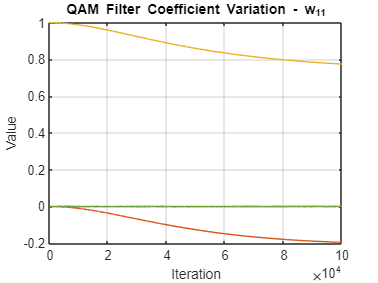

title("QAM Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w12QAM', '-');

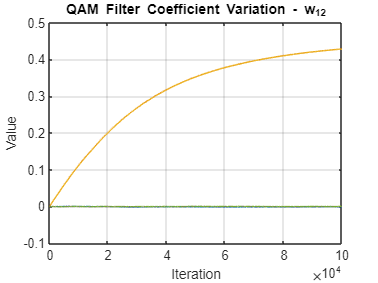

title("QAM Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w21QAM', '-');

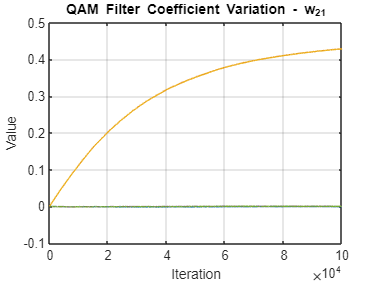

title("QAM Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w22QAM', '-');

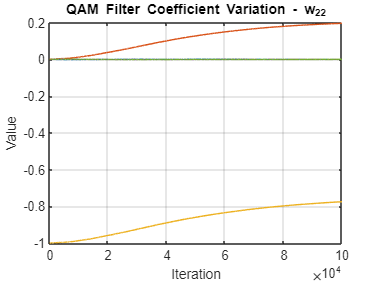

title("QAM Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], pQAM, '-');

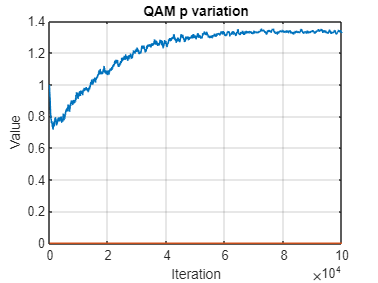

title("QAM p variation")
xlabel("Iteration")
ylabel("Value")
grid on

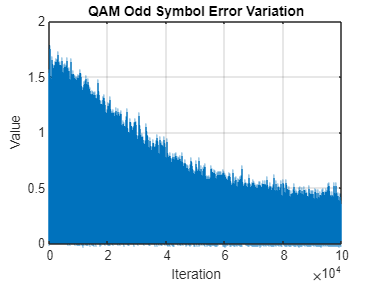


stem([1:size(errQAM(:,1))], abs(errQAM(:,1)), '|');
title("QAM Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

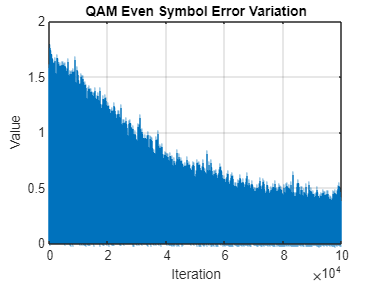


stem([1:size(errQAM(:,2))], abs(errQAM(:,2)), '|');
title("QAM Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

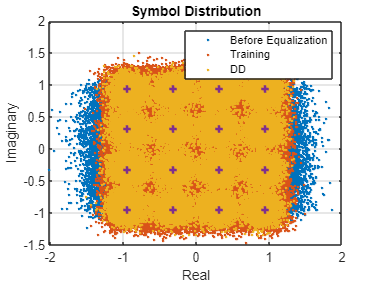


plot(voltageQAM_I(:,1,1)+1i*voltageQAM_Q(:,1,end), '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQAM(1:NRemove,end), '.');
plot(equalizedSymbsQAM(NRemove+1:end,end), '.');
plot(sourceSymbolsQAM, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off


% -----------------------------------------------------------------------------------------

% Shaped

plot([1:size(pQAM_shaped)], w11QAM_shaped', '-');

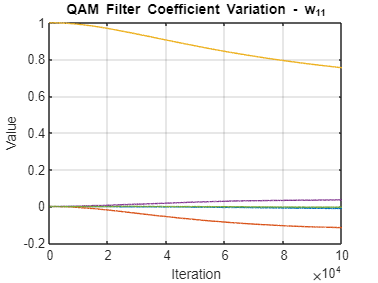

title("QAM Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped)], w12QAM_shaped', '-');

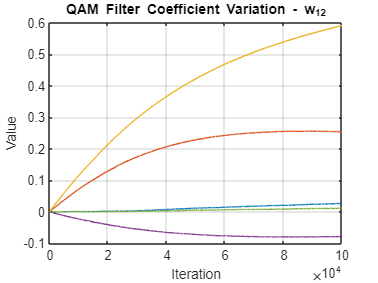

title("QAM Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped)], w21QAM_shaped', '-');

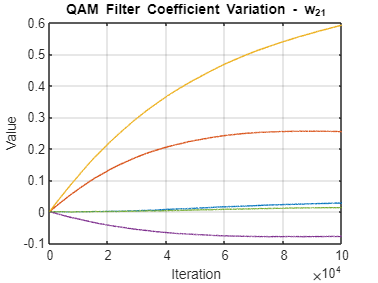

title("QAM Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped)], w22QAM_shaped', '-');

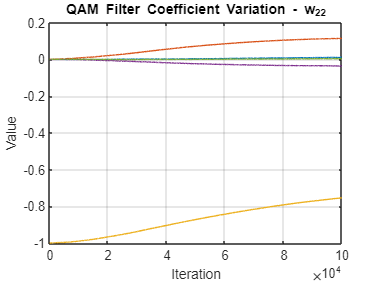

title("QAM Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM_shaped)], pQAM_shaped, '-');

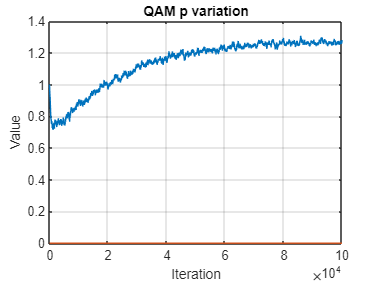

title("QAM p variation")
xlabel("Iteration")
ylabel("Value")
grid on

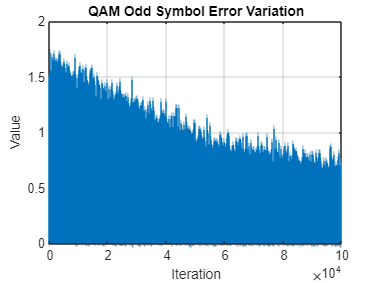


stem([1:size(errQAM_shaped(:,1))], abs(errQAM_shaped(:,1)), '|');
title("QAM Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

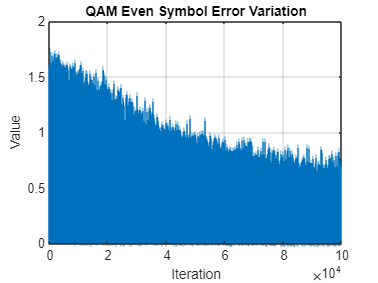


stem([1:size(errQAM_shaped(:,2))], abs(errQAM_shaped(:,2)), '|');
title("QAM Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

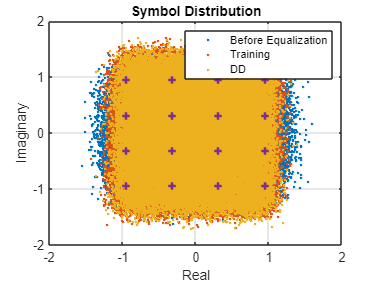


plot(voltageQAM_shaped_filtered(:,1,end), '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbsQAM_shaped(1:NRemove,end), '.');
plot(equalizedSymbsQAM_shaped(NRemove+1:end,end), '.');
plot(sourceSymbolsQAM, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off

## Receiver

### Decoding and Decision

distortedSymbsQAM = voltageQAM_I(1:SpS:end,1,:)+1i*voltageQAM_Q(1:SpS:end,1,:);
distortedSymbsQAM(2:2:end,:,:) = -1*conj(distortedSymbsQAM(2:2:end,:,:)); % Unshaped

distortedSymbsQAM_shaped = voltageQAM_shaped_filtered(1:SpS:end,1,:);
distortedSymbsQAM_shaped(2:2:end,:,:) = -1*conj(distortedSymbsQAM_shaped(2:2:end,:,:)); % Shaped

% Before equalization
IntsQAM_before = qamdemod(reshape(distortedSymbsQAM(:,1,:),NSymb,OpticFEOut_3d), 16, UnitAveragePower=true);
BitsQAM_before = int2bit(IntsQAM_before, 4);
[~, BERQAM_before] = biterr(BitsQAM_before, sourceBitsQAM) % Unshaped

BERQAM_before =     0.4068    0.4033    0.4021    0.4054    0.4119



IntsQAM_shaped_before = qamdemod(reshape(distortedSymbsQAM_shaped(:,1,:),NSymb,OpticFEOut_3d), 16, UnitAveragePower=true);
BitsQAM_shaped_before = int2bit(IntsQAM_shaped_before, 4);
[~, BERQAM_shaped_before] = biterr(BitsQAM_shaped_before, sourceBitsQAM) % Shaped

BERQAM_shaped_before =     0.4069    0.4033    0.4023    0.4050    0.4117



% During Training
IntsQAM_train = qamdemod(equalizedSymbsQAM(1:N1*2,:), 16, UnitAveragePower=true);
BitsQAM_train = int2bit(IntsQAM_train, 4);
[~, BERQAM_train] = biterr(BitsQAM_train, sourceBitsQAM(1:N1*8)) % Unshaped

BERQAM_train =     0.2111    0.1790    0.1529    0.1357    0.1251



IntsQAM_shaped_train = qamdemod(equalizedSymbsQAM_shaped(1:N1*2,:), 16, UnitAveragePower=true);
BitsQAM_shaped_train = int2bit(IntsQAM_shaped_train, 4);
[~, BERQAM_shaped_train] = biterr(BitsQAM_shaped_train, sourceBitsQAM(1:N1*8)) % Shaped

BERQAM_shaped_train =     0.2614    0.2339    0.2150    0.2025    0.1956



if N1*2 < NSymb
    % During Decision-Directed mode
    IntsQAM_dd = qamdemod(equalizedSymbsQAM(N1*2+1:end,:), 16, UnitAveragePower=true);
    BitsQAM_dd = int2bit(IntsQAM_dd, 4);
    [~, BERQAM_dd] = biterr(BitsQAM_dd, sourceBitsQAM(N1*8+1:end)) % Unshaped
    
    IntsQAM_shaped_dd = qamdemod(equalizedSymbsQAM_shaped(N1*2+1:end,:), 16, UnitAveragePower=true);
    BitsQAM_shaped_dd = int2bit(IntsQAM_shaped_dd, 4);
    [~, BERQAM_shaped_dd] = biterr(BitsQAM_shaped_dd, sourceBitsQAM(N1*8+1:end)) % Shaped
end

% Final symbols
IntsQAM_final = qamdemod(equalizedSymbsQAM(NRemove+1:end-NTaps,:), 16, UnitAveragePower=true);
BitsQAM_final = int2bit(IntsQAM_final, 4);
[~, BERQAM_final] = biterr(BitsQAM_final, sourceBitsQAM(NRemove*4+1:end-NTaps*4)) % Unshaped

BERQAM_final =     0.1331    0.0865    0.0475    0.0212    0.0070



IntsQAM_shaped_final = qamdemod(equalizedSymbsQAM_shaped(NRemove+1:end-NTaps,:), 16, UnitAveragePower=true);
BitsQAM_shaped_final = int2bit(IntsQAM_shaped_final, 4);
[~, BERQAM_shaped_final] = biterr(BitsQAM_shaped_final, sourceBitsQAM(NRemove*4+1:end-NTaps*4)) % Shaped

BERQAM_shaped_final =     0.1962    0.1558    0.1239    0.1020    0.0873


### BER vs SNR

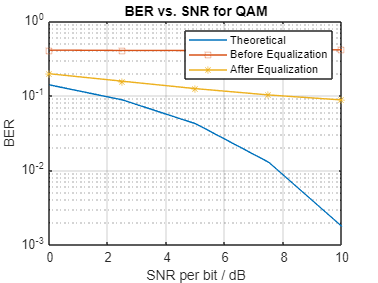

if insertAWGN 
    semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
    hold on
%     semilogy(SNRb_dB, BERQAM_before', '-o');
%     semilogy(SNRb_dB, BERQAM_final', '-*');
    semilogy(SNRb_dB, BERQAM_shaped_before', '-s');
    semilogy(SNRb_dB, BERQAM_shaped_final', '-*');
    title("BER vs. SNR for QAM");
    ylabel("BER");
    xlabel("SNR per bit / dB");
    legend("Theoretical", "Before Equalization", "After Equalization");
    grid on
    hold off
end